time_frame_now = 10;
% noisy signal f*time*mic 
figure; subplot(3,1,1)
plot(abs(squeeze(y_STFT(:,time_frame_now,:))))
% enhanced signal f*time*mic 
subplot(3,1,2)
plot(real(squeeze(S_mvdr_mwfL_stft(:,time_frame_now,:))))
% weight gain mic*f*time 
subplot(3,1,3)
plot(real(squeeze(weight(1,:,time_frame_now)))); hold on; plot(real(squeeze(weight(2,:,time_frame_now))))
figure ; subplot(2,1,1)
plot(imag(squeeze(weight(1,:,time_frame_now)))); hold on; plot(imag(squeeze(weight(2,:,time_frame_now))));
hold off;
subplot(2,1,2)
plot(abs(squeeze(weight(1,:,time_frame_now)))); hold on; plot(abs((squeeze(weight(2,:,time_frame_now)))));
hold off

aa=weight - weight_com;
ee = mvdr_n1 - mvdr_n2;
sum_ee = sum(sum(ee))
figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(mvdr_n1))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(mvdr_n2))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref non reverberant mic');

sig = sqrt((10.^((TX_Mask -90)./10)./2)*nfft^2);


tt = psd2spl(sig,nfft);
figure; subplot(2,1,1);
imagesc(1:N_frames, f,tt); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');

subplot(2,1,2);
imagesc(1:N_frames, f,TX_Mask); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');
figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(x_STFT(:,:,1)).^2),[-100,0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('Speech Presence Probability for ref mic');

subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(sig.^2),[-100,0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('Speech Presence Probability for ref mic');
a1 = squeeze(abs(x_STFT(:,:,1)).^2);
a2 = sig.^2;
sum_ee = sum(sum( - sig.^2))

figure
rng default
Fs = 8000;
t = 0:1/Fs:1-1/Fs;
x = cos(2*pi*2000*t) ;
N = 512;
xdft = fft(x,N);
xdft = xdft(1:N/2+1);
psdx = (1/(N*Fs)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/N:Fs/2;

plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')


source_filename{1} = 'speech1.wav';
siglength = 5; 
num_mics = 2;
[aa, bb] = audioread(source_filename{1},'native');

% signal  = resample(source_signals_raw{1},fs_RIR,source_signals_raw{2});

% SPL = splMeter
% SPL = splMeter(Name,Value)
% % b = hz2bark([20,8000]);
%        barkVect = linspace(b(1),b(2),32);
%        hzVect = bark2hz(barkVect);
%        plot(barkVect,hzVect,'o')
%        title('Bark vs Hz')
%        xlabel('Bark')
%        ylabel('Hz')
%        grid on

% figure; 
% subplot(2,1,1);
% imagesc(1:N_frames, f,mag2db(abs(rho_r))); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('real phi_r');
% subplot(2,1,2);
% imagesc(1:N_frames, f,mag2db(abs(rho_rev))); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
%     title('phi_r EVD based on estimated Rxx');
figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(rho_r))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('real phi_r');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(rho_rev_realx))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('phi_r EVD based on real Rxx');
% figure; subplot(2,1,1)
% plot(mag2db(abs(rho_r(:,311))));
% subplot(2,1,2)
% plot(mag2db(abs(rho_rev(:,311))));
figure; 
plot(mag2db(abs(rho_rev_realx(2:257,50))));title('estimated rho_r based on real Rxx')
hold on;
plot(mag2db(abs(rho_r(2:257,50))))

legend('estimated rho','real rho r')


Rxx_esti = cell(N_freqs,1);
for k = 2:257
Rxx_esti{k} = rho_s(k,311) * h_steer(:,k)*h_steer(:,k)'+ rho_r(k,311)*gama{k};
Rxx1_esti(k,1) = Rxx_esti{k}(1,1);
aa(k,1) = rho_s(k,311)+rho_r(k,311);
Rxx1(k,1) = Rxx{k}(1,1);
end
Rxx;
figure; subplot(2,1,1);
plot(abs(aa)); title('estimated Rxx on 1mic based on formula');
subplot(2,1,2);
plot(abs(Rxx1));title('time average Rxx on 1 mic ');

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(x_STFT(:,:,1).^2))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('real phi_r');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(xe_STFT(:,:,1).^2+xr_STFT(:,:,1).^2))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('phi_r EVD based on real Rxx');
figure; subplot(2,1,1);
plot(abs(x_STFT(:,50,1).^2)); title('real power');
subplot(2,1,2);
plot(abs(xe_STFT(:,50,1).^2+xr_STFT(:,50,1).^2));title('assemble power ');
figure; subplot(2,1,1);
plot(abs(xe_STFT(:,50,1).^2)); title('real power');
subplot(2,1,2);
plot(abs(xr_STFT(:,50,1).^2));title('assemble power ');

Ry1 = zeros(N_freqs, N_frames);
Rn1 = zeros(N_freqs, N_frames);
Rx1 = zeros(N_freqs, N_frames);
Rx2 = zeros(N_freqs, N_frames);
Rx3 = zeros(N_freqs, N_frames);
model.lambda = 0.98; 
model.alpha = 0.33; 
v = zeros(N_freqs, N_frames);
prioiSNR = zeros(N_freqs, N_frames);postSNR = zeros(N_freqs, N_frames);
tic
for l = 1:N_frames
    for k = 2:N_freqs
        if(SPP(k,l)>model.SPP_thr)
          if l==1
              aa = 0;
              bb=0;
          else
              aa = Ry1(k,l-1);
              bb=Rn1(k,l-1);
          end
        Ry1(k,l) = model.lambda* aa+(1-model.lambda).* abs(y_STFT(k,l,1))^2;
        Rn1(k,l)=bb;
         % speech + noise
        else
        % noise only
          if l==1
              aa = 0;
              bb = 0;
          else
              aa = 0.01*Ry1(k,l-1);
              bb = Rn1(k,l-1);
          end
        Rn1(k,l) = model.lambda* bb+(1-model.lambda).* abs(y_STFT(k,l,1))^2;      
        Ry1(k,l) = Rn1(k,l);
        end   
         if l==1
              xx = 0;
          else
              xx = Rx1(k,l-1);
          end
      % ture Rxx time average =X.^2
        Rx1(k,l) = model.alpha* xx+(1-model.alpha).* abs(x_STFT(k,l,1))^2;
      % direct subtraction estimation Rxx = Ryy - Rnn
        Rx2(k,l) = (abs(Ry1(k,l))>abs(Rn1(k,l)))*(abs(Ry1(k,l))-abs(Rn1(k,l)))+ ...
                   (abs(Ry1(k,l))<=abs(Rn1(k,l)))*(0.01*Rn1(k,l));
      % dicesion directed estimated
      a = 0.6;  
%       noise_power =  abs(n_STFT(k,l,1))^2;
%       noise_power = noisePowMat_y(k,l);
      noise_power = Rn1(k,l);
      postSNR(k,l) = abs(y_STFT(k,l,1))^2/noise_power;
     if l==1 ;resi = 0;else ;resi = abs(Rx3(k,l-1))/noise_power; end
      prioiSNR(k,l) = a * resi +(1-a)*max(0,postSNR(k,l)-1);
      v(k,l) =  (prioiSNR(k,l)/(1+prioiSNR(k,l)))*postSNR(k,l);
      v(k,l)  = min(500,v(k,l));
      % mmse high snr convergence
%       sig_spectral = (prioiSNR(k,l)/(1+prioiSNR(k,l)))*y_STFT(k,l,1);
      % mmse complete
%       mu = 1;
     sig_spectral = gamma(1.5)*(sqrt(v(k,l))/postSNR(k,l))*exp(-v(k,l)/2)...
         *((1+v(k,l))*besseli(0,v(k,l)/2) + v(k,l)*besseli(1,v(k,l)/2))...
         *y_STFT(k,l,1);
%    
      Rx3(k,l) = sig_spectral*conj(sig_spectral);
      Rx4(k,l) = Ry1(k,l)-noisePowMat_y(k,l);
    end  
end
toc

历时 2.236114 秒。


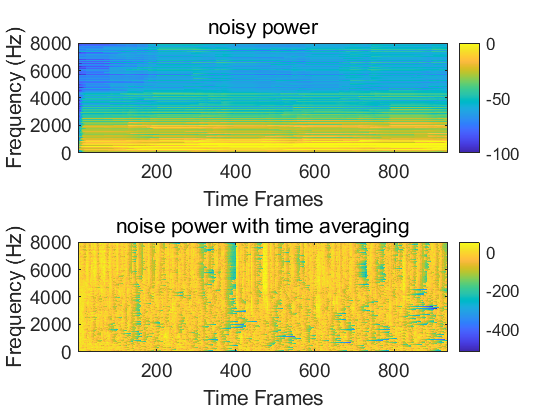

% fre = 161;
% figure ; subplot(2,1,1)
% plot(abs(Rx1(fre,:))); 
% hold on; plot(abs(Rx2(fre,:)));
% legend({'real','estimated'});
% subplot(2,1,2)
% plot(abs(Ry1(fre,:))); 
% hold on; plot(abs(Rn1(fre,:)));
% legend({'noisy','noise'});

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(Rn1)),[-100,0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('noisy power');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(v)); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('noise power with time averaging');

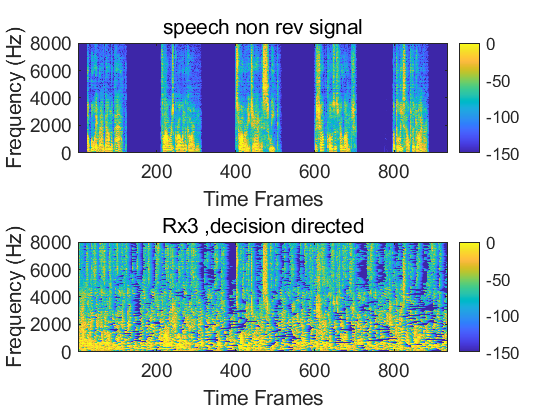

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(xe_STFT(:,:,1).^2)),[-150,0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('speech non rev signal');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(Rx3)),[-150,0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('Rx3 ,decision directed');

% figure; subplot(2,1,1);
% imagesc(1:N_frames, f,mag2db(abs(xe_STFT(:,:,1).^2)),[-150,0]); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ...
%     ylabel('Frequency (Hz)'), title('non rev speech');
% subplot(2,1,2);
% imagesc(1:N_frames, f,mag2db(abs(Rx2)),[-150,0]); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
%     title('Rx2 based on spectral subtraction ');
% figure; subplot(2,1,1);
% imagesc(1:N_frames, f,mag2db(abs(xe_STFT(:,:,1).^2)),[-150,0]); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ...
%     ylabel('Frequency (Hz)'), title('non rev speech');
% subplot(2,1,2);
% imagesc(1:N_frames, f,mag2db(abs(Rx4)),[-150,0]); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
%     title('Rx4  ');

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(n_STFT(:,:,1)).^2),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('noisy signal');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(noisePowMat_y)),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('noise ');

figure; subplot(2,1,1);
imagesc(1:N_frames, f,SPP_y); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('noisy signal');
subplot(2,1,2);
imagesc(1:N_frames, f,SPP); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('noise ');



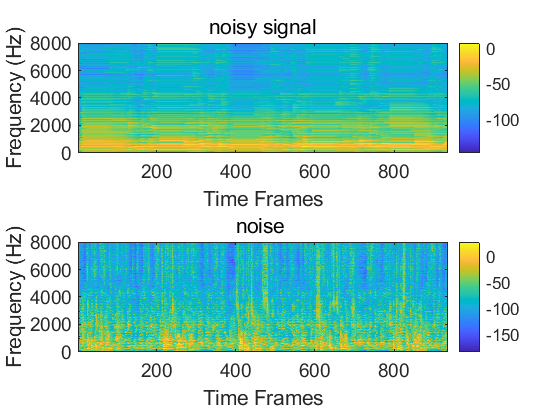

Rnn = cell(N_freqs,1);  Rnn(:) = {1e-6*randn(num_mics,num_mics)};      % Noise Only (NO) corr. matrix. Initialize to small random values
Ryy = cell(N_freqs,1);  Ryy(:) = {1e-6*randn(num_mics,num_mics)};      % Speech + Noise (SPN) corr. matrix. Initialize to small random values
Rxx = cell(N_freqs,1);  Rxx(:) = {1e-6*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rxx_real = cell(N_freqs,1);  Rxx_real(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rxx_esti = cell(N_freqs,1);  Rxx_esti(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rnn_real = cell(N_freqs,1);  Rnn_real(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rx3 = zeros(N_freqs,N_frames);
for l=1:N_frames % Time index
    for k = 2:N_freqs % Freq index
                
Y_kl = squeeze(y_STFT(k,l,1:num_mics));  % M x 1 noisy mic sigs for this freq and time frame
X_kl = squeeze(x_STFT(k,l,1:num_mics));
N_kl = squeeze(n_STFT(k,l,1:num_mics));

H_optimal{k} = Rx3(k,l)*inv(Rnn{k})*h_steer(:,k);

% ## Update the correlation matrices using the forgetting factor.
% Threshold the SPP in order to distinguish between periods of speech and non-speech activity
if(SPP(k,l)>=0.9)
 Ryy{k} = model.lambda*Ryy{k}+(1-model.lambda).* Y_kl* Y_kl';
% speech + noise
else
% noise only
a = 0.9;
 Rnn{k} = a*Rnn{k}+(1-a).* Y_kl* Y_kl'; % N*N' is not available in real situation 
%              Ryy{k} = Rnn{k};
end           
Rxx_real{k} = (model.alpha*Rxx_real{k}+(1-model.alpha).* X_kl* X_kl');
Rnn_real{k} = (model.alpha*Rnn_real{k}+(1-model.alpha).* N_kl* N_kl');
Rn1(k,l) = Rnn_real{k}(1,1);Rn2(k,l) = Rnn{k}(1,1);
%       noise_power = Rnn{k}(1,1);
   noise_power = noisePowMat_y(k,l);
      postSNR(k,l) = abs(y_STFT(k,l,1))^2/noise_power;
     if l==1 ;resi = 0;else ;resi = abs(Rx3(k,l-1))/noise_power; end
      prioiSNR(k,l) = a * resi +(1-a)*max(0,postSNR(k,l)-1);
      v(k,l) =  (prioiSNR(k,l)/(1+prioiSNR(k,l)))*postSNR(k,l);
      v(k,l)  = min(500,v(k,l));
      % mmse high snr convergence
%       sig_spectral = (prioiSNR(k,l)/(1+prioiSNR(k,l)))*y_STFT(k,l,1);
      % mmse complete
%       mu = 1;
     sig_spectral = gamma(1.5)*(sqrt(v(k,l))/postSNR(k,l))*exp(-v(k,l)/2)...
         *((1+v(k,l))*besseli(0,v(k,l)/2) + v(k,l)*besseli(1,v(k,l)/2))...
         *y_STFT(k,l,1);
%    
      Rx3(k,l) = sig_spectral*conj(sig_spectral);
    end
end
figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(Rn2))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('noisy signal');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(Rx3))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('noise ');

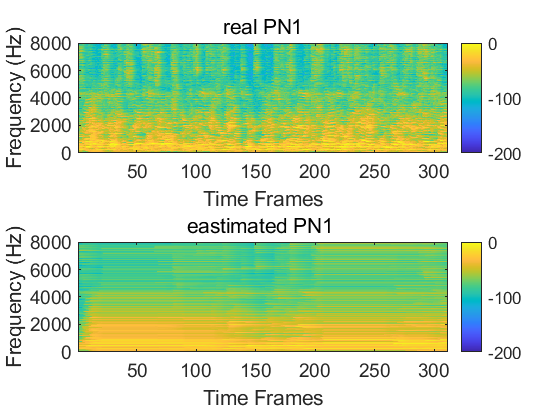

Rnn = cell(N_freqs,1);  Rnn(:) = {1e-6*randn(num_mics,num_mics)};      % Noise Only (NO) corr. matrix. Initialize to small random values
Ryy = cell(N_freqs,1);  Ryy(:) = {1e-6*randn(num_mics,num_mics)};      % Speech + Noise (SPN) corr. matrix. Initialize to small random values
Rxx = cell(N_freqs,1);  Rxx(:) = {1e-6*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rxx_real = cell(N_freqs,1);  Rxx_real(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rxx_esti = cell(N_freqs,1);  Rxx_esti(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rnn_real = cell(N_freqs,1);  Rnn_real(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       


for l=1:N_frames % Time index
    for k = 2:N_freqs % Freq index
                
Y_kl = squeeze(y_STFT(k,l,1:num_mics));  % M x 1 noisy mic sigs for this freq and time frame
X_kl = squeeze(x_STFT(k,l,1:num_mics));
N_kl = squeeze(n_STFT(k,l,1:num_mics));
% ## Update the correlation matrices using the forgetting factor.
% Threshold the SPP in order to distinguish between periods of speech and non-speech activity
if(SPP(k,l)>model.SPP_thr)
 Ryy{k} = model.lambda*Ryy{k}+(1-model.lambda).* Y_kl* Y_kl';
% speech + noise
else
% noise only
a = 0.9;
 Rnn{k} = a*Rnn{k}+(1-a).* Y_kl* Y_kl'; % N*N' is not available in real situation 
%              Ryy{k} = Rnn{k};
end           
Rxx_real{k} = (model.alpha*Rxx_real{k}+(1-model.alpha).* X_kl* X_kl');
Rnn_real{k} = (model.alpha*Rnn_real{k}+(1-model.alpha).* N_kl* N_kl');
Rn1(k,l) = Rnn_real{k}(1,1);Rn2(k,l) = Rnn{k}(1,1);

    end
end


figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(Rn1)),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('real PN1');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(Rn2)),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('eastimated PN1 ');

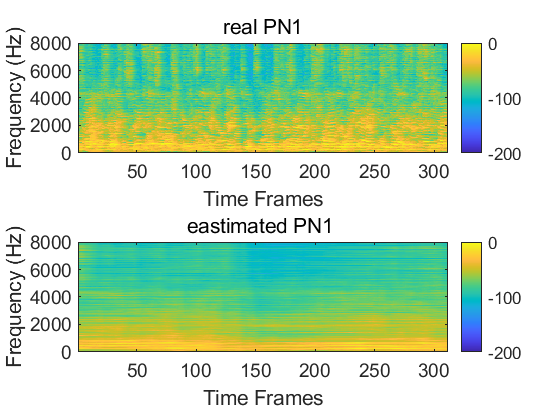

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(Rn1)),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('real PN1');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(noisePowMat_y),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('eastimated PN1 ');

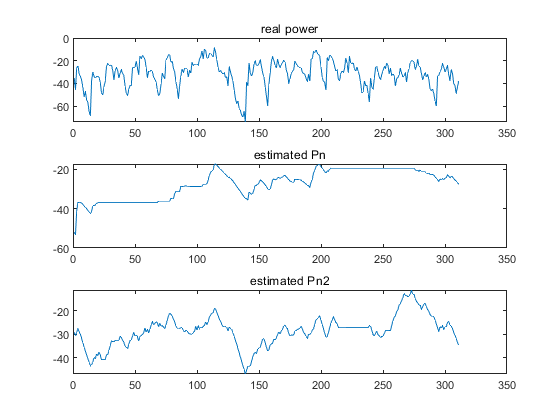

figure; subplot(3,1,1);fm = 10;
plot(mag2db(abs(Rn1(fm,:)))); title('real power');
subplot(3,1,2);
plot(mag2db(abs(Rn2(fm,:))));title('estimated Pn');
subplot(3,1,3);
plot(mag2db(noisePowMat_y(fm,:)));title('estimated Pn2');

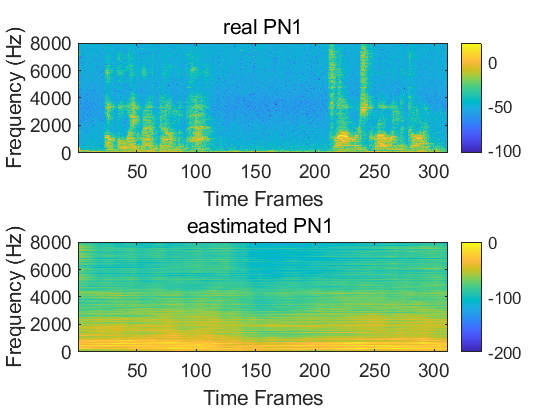

S_enhanced = squeeze(S_MWF(:,:,1));

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(S_enhanced))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('real PN1');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(noisePowMat_y),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('eastimated PN1 ');

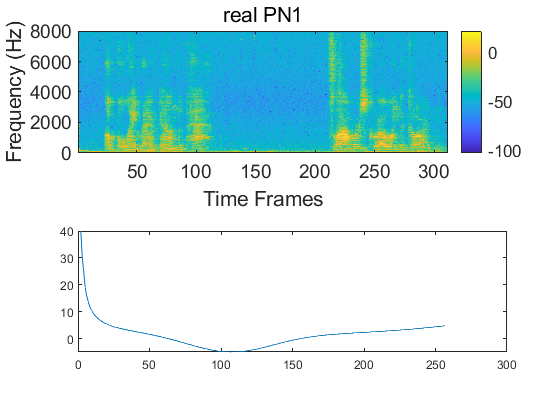

Tq = 3.64*(f/1000).^-0.8 -6.5*exp(-0.6*(f/1000-3.3).^2)+0.001*(f/1000).^4;
Tq(2) = 40;Tq(3) = 30;Tq(4) = 25;
plot(Tq)

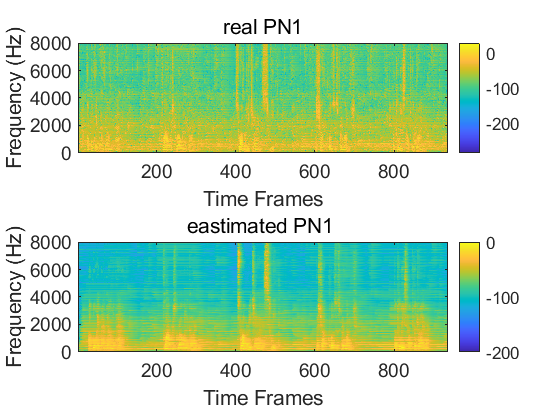


figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(Rx3))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ...
    ylabel('Frequency (Hz)'), title('real PN1');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(noise_mvdr),[-200 0]); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('eastimated PN1 ');